filelist = [ "data_21-Mar-2025_09-26-10.mat" ,
"data_21-Mar-2025_09-28-59.mat" ,
"data_21-Mar-2025_09-32-07.mat" ,
"data_21-Mar-2025_09-34-30.mat" ,
"data_21-Mar-2025_09-37-20.mat" ,
"data_21-Mar-2025_09-42-10.mat" ,
"data_21-Mar-2025_09-43-30.mat" ,
"data_21-Mar-2025_09-51-00.mat" ,
"data_21-Mar-2025_09-52-42.mat" ,
"data_21-Mar-2025_09-55-40.mat" ,
"data_21-Mar-2025_10-02-58.mat" ,
"data_21-Mar-2025_10-09-11.mat" ,
"data_21-Mar-2025_10-10-37.mat" ,
"data_21-Mar-2025_10-12-01.mat" ,
"data_21-Mar-2025_10-17-54.mat" ,
"data_21-Mar-2025_10-21-14.mat" ,
"data_21-Mar-2025_10-24-43.mat" ,
"data_21-Mar-2025_10-29-46.mat" ,
"data_21-Mar-2025_10-36-06.mat" ];

exp_id = 19

exp_id = 19

data =          0    0.0020    0.0040    0.0060    0.0080    0.0100    0.0120    0.0140    0.0160    0.0180    0.0200    0.0220    0.0240    0.0260    0.0280    0.0300    0.0320    0.0340    0.0360    0.0380    0.0400    0.0420    0.0440    0.0460    0.0480    0.0500    0.0520    0.0540    0.0560    0.0580    0.0600    0.0620    0.0640    0.0660    0.0680    0.0700    0.0720    0.0740    0.0760    0.0780    0.0800    0.0820    0.0840    0.0860    0.0880    0.0900    0.0920    0.0940    0.0960    0.0980
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

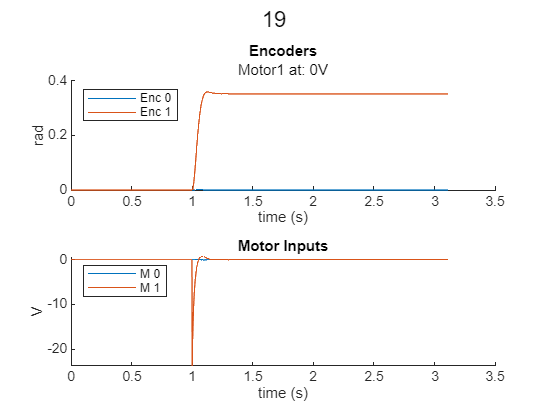

filename = "lab3/data/pid/" + filelist(exp_id);
load(filename,"data")

smartPlotEncVoltage(data,exp_id,false);


t = data(1,:)-1;
y = rad2deg(data(3,:));
y_ref = 20*(0.5 + 0.5*sign(t));

figure
plot(t,y_ref,":")
hold on
plot(t,y,"b")

xlim([0 0.3])
title("Step Response M1 (PD)")
ylabel("position (deg)")
xlabel("time (s)")

% PID0
Kp = -21.4;
Kd = -0.43;

C0 = pid(Kp,0,Kd);

dc_gain1 = -1.4684; % v/(rad/s)
tau1 = 1/24.4499;   % 1/s

G1 = tf([dc_gain1],[tau1 1 0]);

L1 = C0*G1;
L1d = c2d(L1,1/500);

T_pd = feedback(L1d,1);

[y_sim,tOut] = step(T_pd);
stepinfo(T_pd)

ans = struct with fields:
         RiseTime: 0.0640
    TransientTime: 0.1940
     SettlingTime: 0.1940
      SettlingMin: 0.9123
      SettlingMax: 1.0540
        Overshoot: 5.3976
       Undershoot: 0
             Peak: 1.0540
         PeakTime: 0.1300


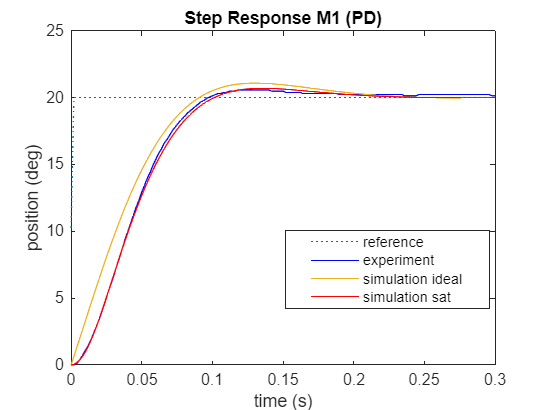

plot(tOut,20*y_sim)


% PID0 + sat
pidq = "lab3/pidq";
h = load_system(pidq);
simIn = Simulink.SimulationInput(pidq);
simIn= setVariable(simIn,"setP",deg2rad(20));
simIn= setVariable(simIn,"Kp",Kp);
simIn= setVariable(simIn,"Kd",Kd);
simIn= setVariable(simIn,"dcg",dc_gain1);
simIn= setVariable(simIn,"tau",tau1);
out = sim(simIn,"UseFastRestart","on");

% out = sim("lab3/pidq");

t_sim_sat = out.yout{1}.Values.Time;
y_sim_sat = out.yout{1}.Values.Data;
plot(t_sim_sat,y_sim_sat,"r")



hold off

legend(["reference","experiment",  "simulation ideal","simulation sat"], "Position", [0.5565 0.2654 0.3041, 0.1544])